warning('off');

load('..\LetterTrainingDataset\Training28.mat');
X_train = Value;
X_train = double(X_train)/255;
y_train = Index;
map = Map;
load('..\LetterTrainingDataset\Testing28.mat');
X_test = Value;
X_test = double(X_test)/255;
y_test = Index;

% X_train = [0  0;0 1; 1 1; 1 0];
% y_train = [48; 49; 49; 49];
% map = '01';
% X_test = [0 1; 0 0; 1 0; 1 1];
% y_test = [49; 48; 49; 49];

[y_est, Weights] = fnn(X_train, y_train, X_test, y_test, map);

% [y_est, ~] = fnn(X_test, Weights);

save('Acc494Weights.mat','Weights');

Epoch 1: 29/1000
Epoch 2: 36/1000
Epoch 3: 47/1000
Epoch 4: 55/1000
Epoch 5: 67/1000
Epoch 6: 81/1000
Epoch 7: 102/1000
Epoch 8: 123/1000
Epoch 9: 161/1000
Epoch 10: 190/1000
Epoch 11: 216/1000
Epoch 12: 253/1000
Epoch 13: 262/1000
Epoch 14: 287/1000
Epoch 15: 296/1000
Epoch 16: 314/1000
Epoch 17: 330/1000
Epoch 18: 350/1000
Epoch 19: 360/1000
Epoch 20: 379/1000
Epoch 21: 388/1000
Epoch 22: 402/1000
Epoch 23: 410/1000
Epoch 24: 417/1000
Epoch 25: 427/1000
Epoch 26: 423/1000
Epoch 27: 424/1000
Epoch 28: 428/1000
Epoch 29: 427/1000
Epoch 30: 427/1000
Epoch 31: 432/1000
Epoch 32: 436/1000
Epoch 33: 436/1000
Epoch 34: 442/1000
Epoch 35: 442/1000
Epoch 36: 448/1000
Epoch 37: 449/1000
Epoch 38: 453/1000
Epoch 39: 457/1000
Epoch 40: 459/1000
Epoch 41: 459/1000
Epoch 42: 461/1000
Epoch 43: 459/1000
Epoch 44: 465/1000
Epoch 45: 460/1000
Epoch 46: 470/1000
Epoch 47: 466/1000
Epoch 48: 470/1000
Epoch 49: 471/1000
Epoch 50: 475/1000
Epoch 51: 474/1000
Epoch 52: 476/1000
Epoch 53: 480/1000
Epoch 54

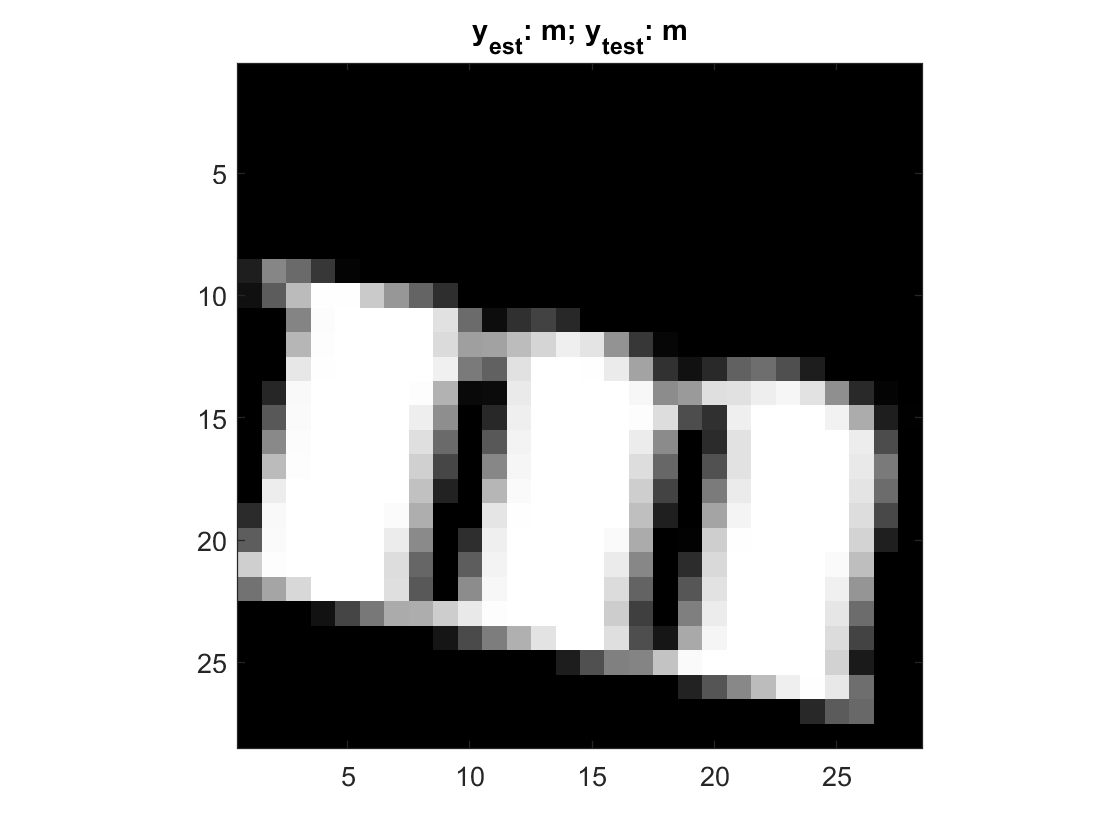

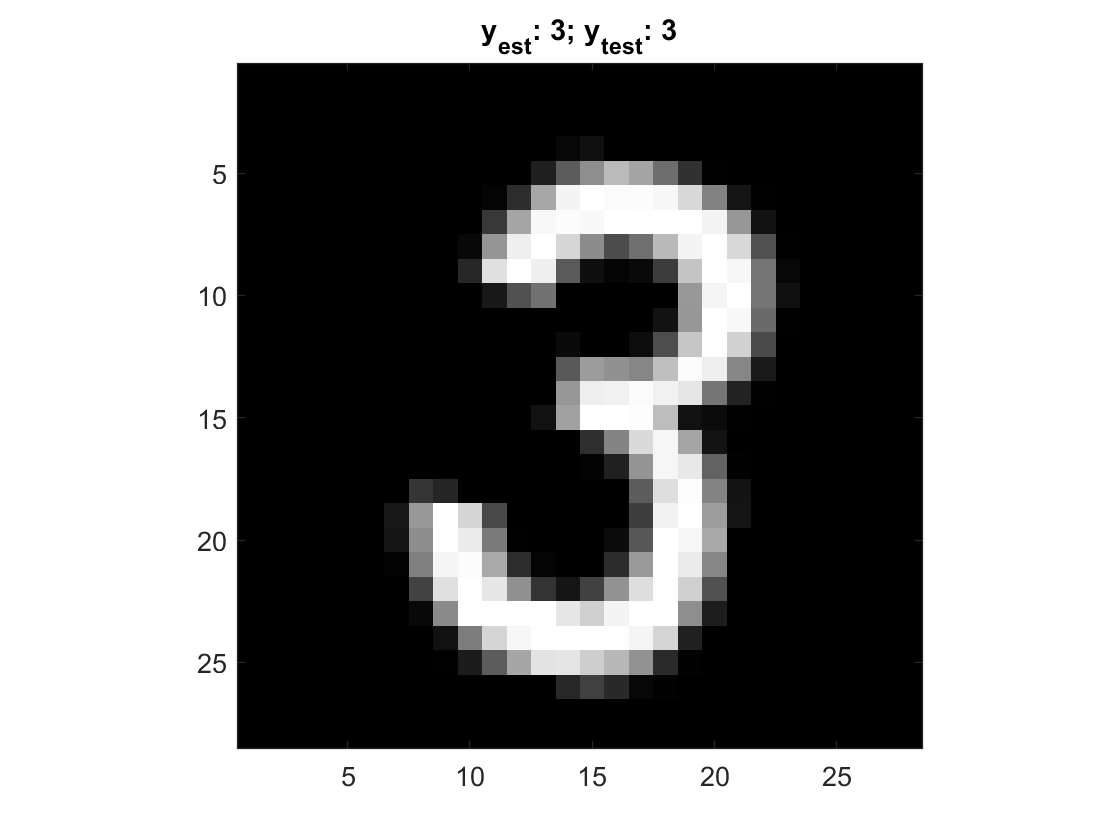

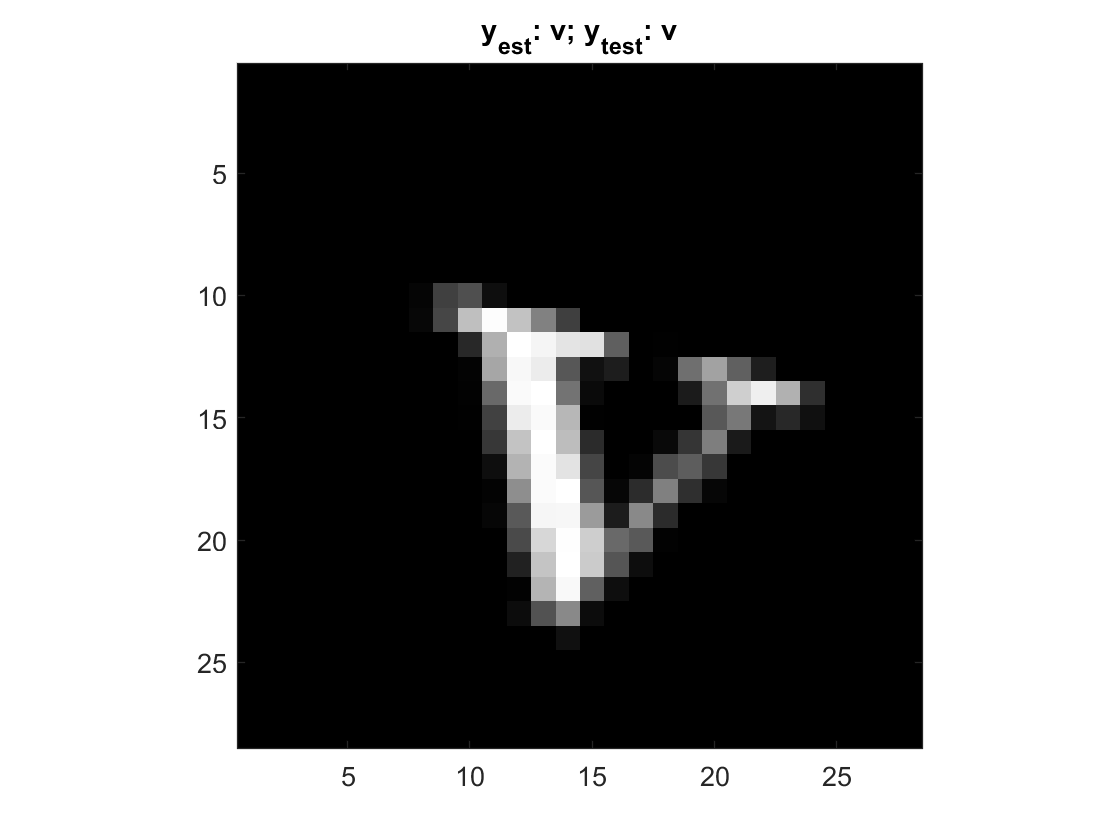

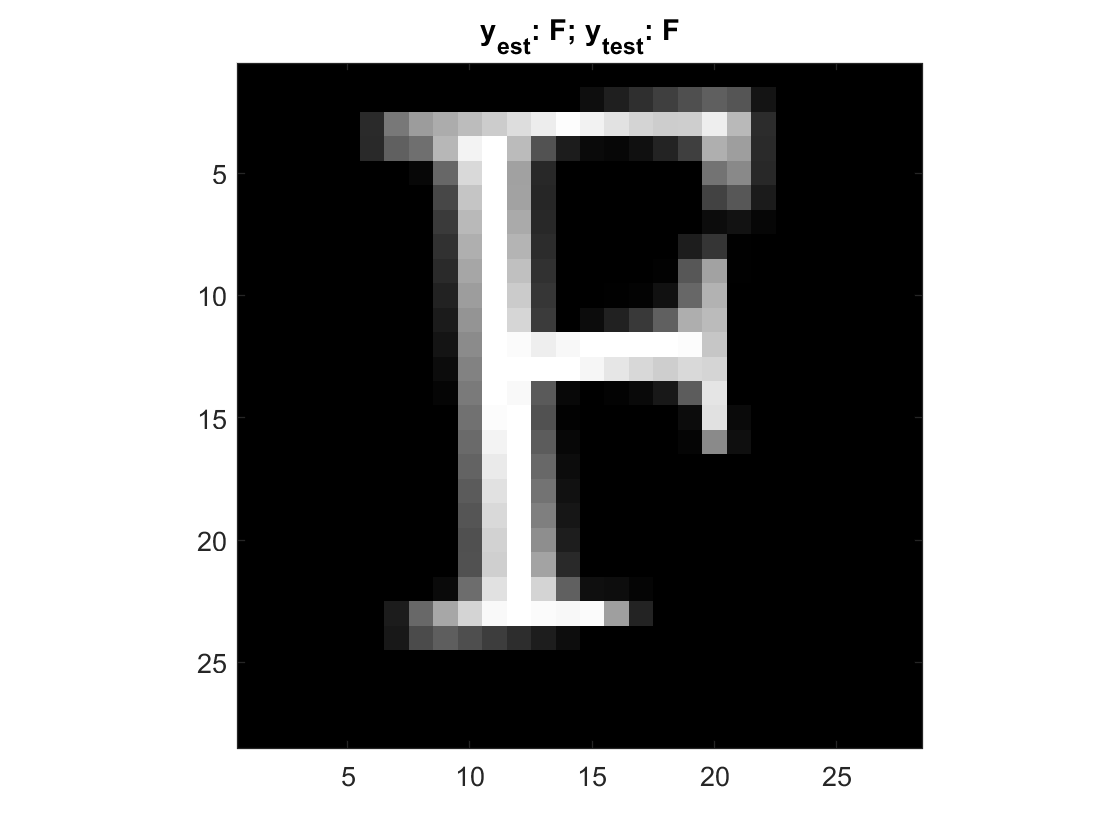

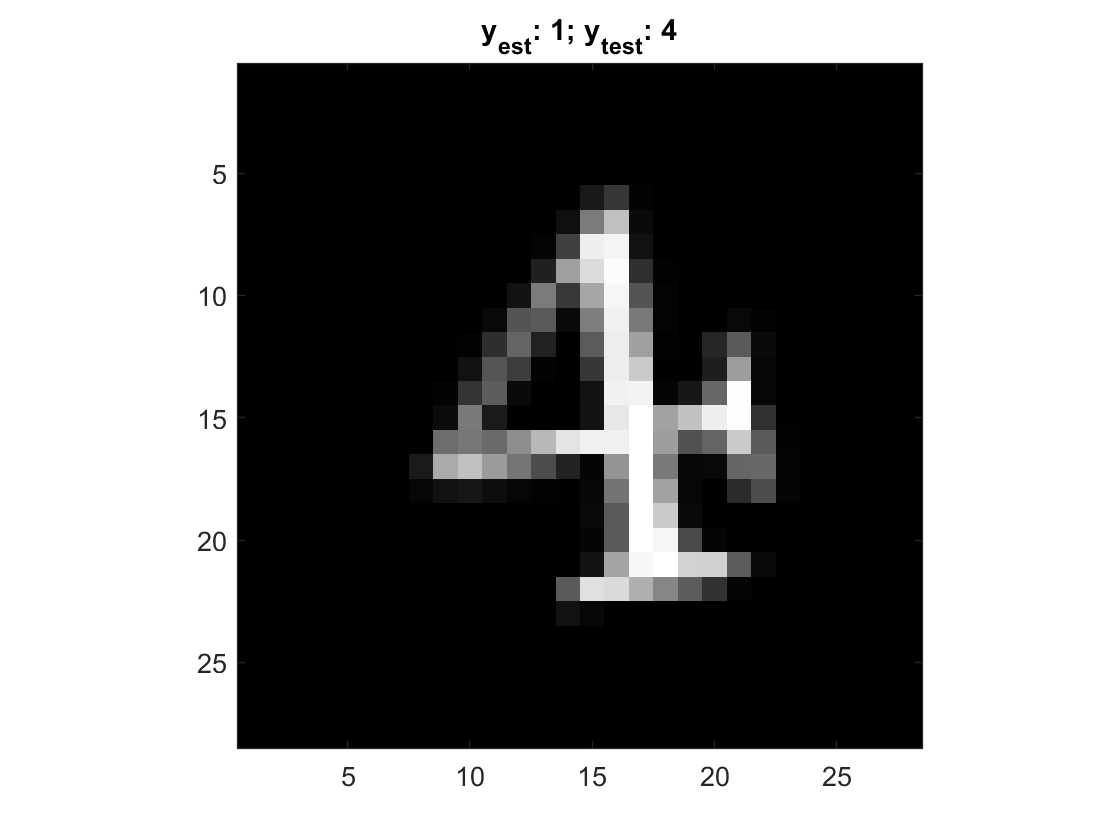

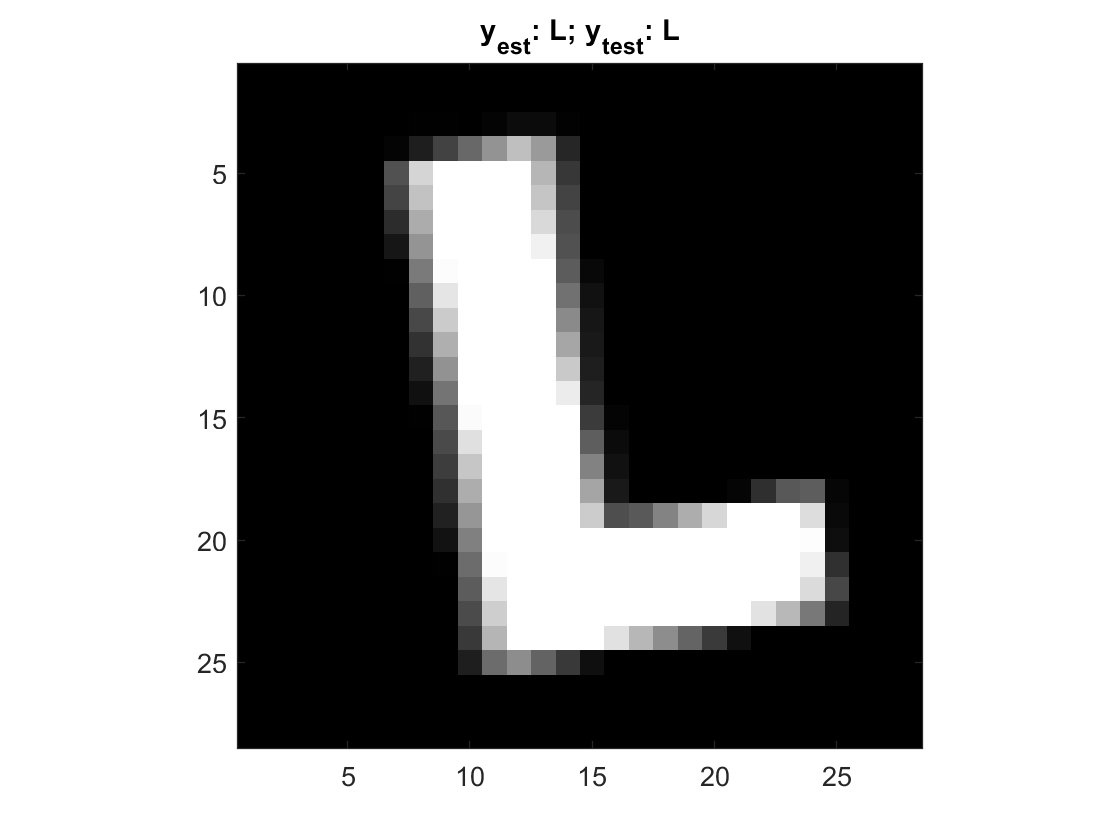

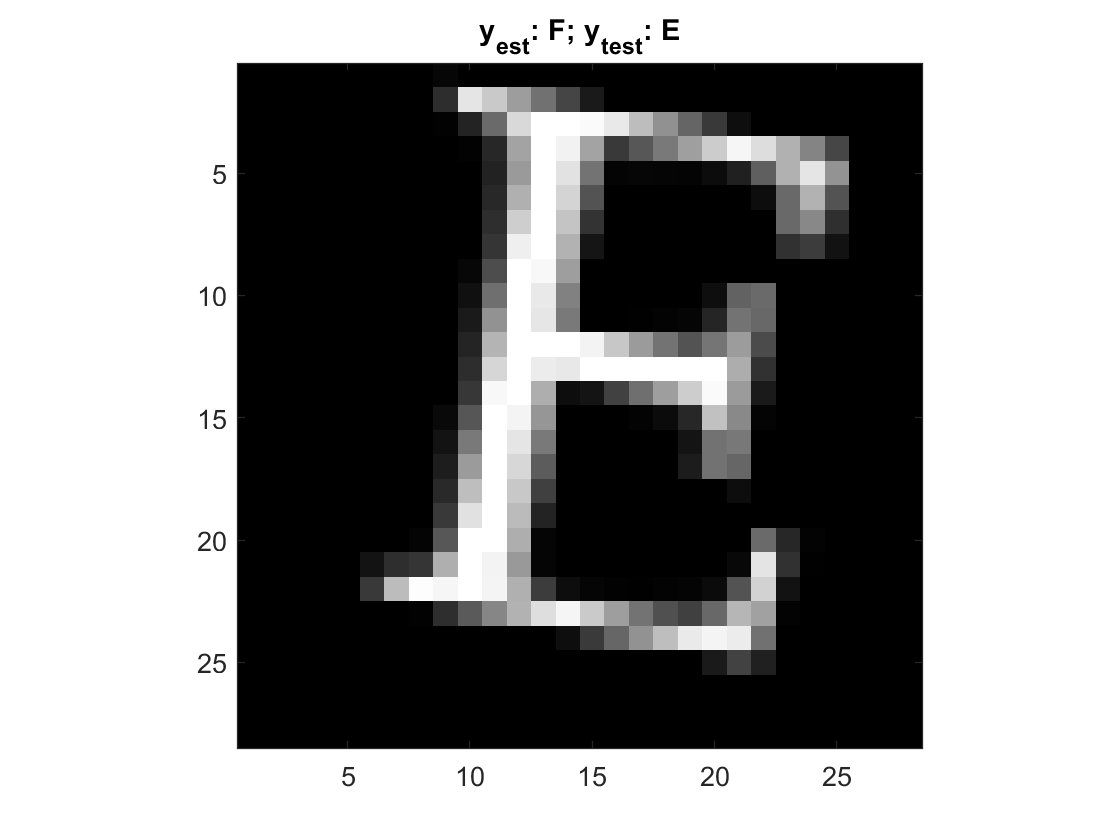

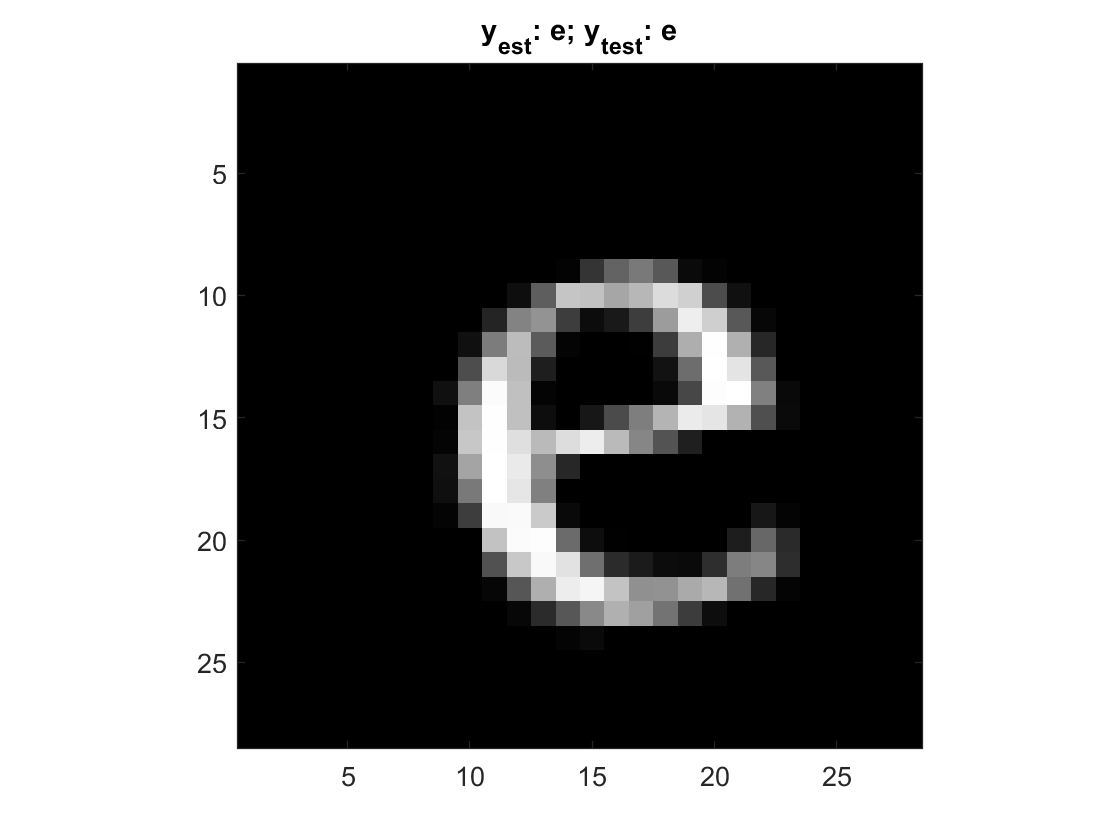

for n = 1:20
    I = uint8(reshape(X_test(n,:),[28,28])*255);



    figure; image(I); pbaspect([1 1 1]); colormap(gray(256));
    title(['y_{est}: ', char(map(y_est(n))), '; y_{test}: ', char(y_test(n))]);
end